clear;

## Question 4

moler #11.5

## (a)

**u_xx + u_yy = p(x,y)    x in [-3,3]    u(x,y) = 0 on boundary**

% preamble
L = 6;
N = 20;
n = N+1;
h = L/N;
x = -L/2:h:L/2;
[X,Y] = meshgrid(x,x);

% solving for p(x,y)
F = peaks(X(2:end-1, 2:end-1), Y(2:end-1, 2:end-1));
P = zeros(n,n);
P(2:end-1, 2:end-1) = F;
P = reshape(P, n^2, 1);

% finding indices of boundary of mesh
bdTop = 1:n;
bdLeft = 1:n:1+(n-1)*n;
bdBot = 1+(n-1)*n:n^2;
bdRight = n:n:n^2;
boundaryIndex = [bdTop bdLeft bdBot bdRight];

% forming spatial differencing matrix
e = ones(n^2,1);
D = spdiags([e e -4*e e e], [-n -1 0 1 n], n^2, n^2);
I = speye(n^2);
D(boundaryIndex,:) = I(boundaryIndex,:);
D = D/h^2;

% solving for U
U = D\P;
U = reshape(U, n, n);

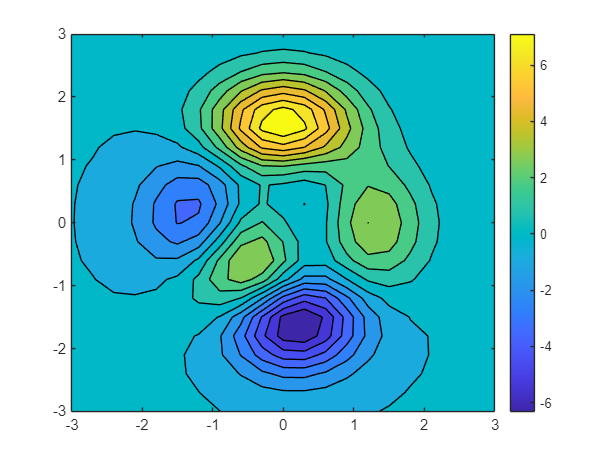

% plotting
fig1 = figure();
contourf(X,Y,peaks(X,Y),15);
colorbar;

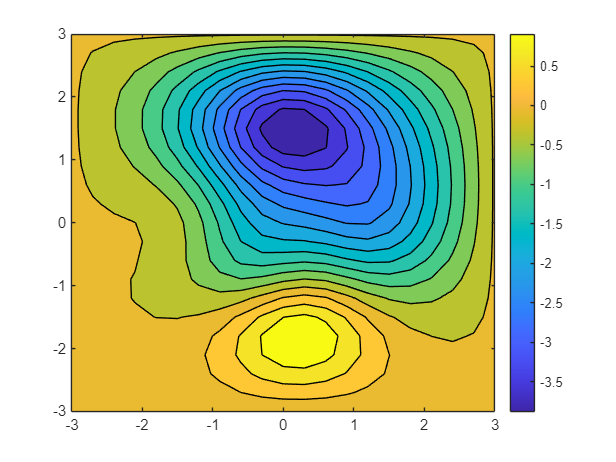

fig2 = figure();
contourf(X,Y,U,15);
colorbar;

## (b)

**u_t = u_xx + u_yy - p(x,y)    x in [-3,3]    u(x,y,t) = 0 on boundary    u(x,y,0) = 0**

x = [-3 3];
N = 50;
T = [0 60];
options = ['p' 'z' 'z'];
[t,U,X,Y] = heat2D(x,N,T,options);

M(length(t)) = struct('cdata', [], 'colormap', []);

fig5 = figure();

zMin = floor(min(min(U,[],2))); 
zMax = ceil(max(max(U,[],2)));
ax = gca;
axis(ax, [-3 3 -3 3 zMin zMax], 'manual');
ax.NextPlot = 'replaceChildren';

fig5.Visible = 'off';
num = floor(length(t)/30)*30;
for i = 1 : num
    Z = U(i,:);
    Z = reshape(Z,N,N);
    surf(X,Y,Z);
    % contourf(X,Y,Z);
    % colorbar;
    drawnow
    M(i) = getframe;
end
fig5.Visible = 'on';
movie(M,1,30);

## (c)

**u_t = u_xx + u_yy    x in [-3,3]    u(x,y,t) = p(x,y) on boundary    u(x,y,0) = p(x,y)**

x = [-3 3];
N = 30;
T = [0 30];
options = ['z' 'p' 'p'];
[t,U,X,Y] = heat2D(x,N,T,options);

M(length(t)) = struct('cdata', [], 'colormap', []);

fig5 = figure();

zMin = floor(min(min(U,[],2))); 
zMax = ceil(max(max(U,[],2)));
ax = gca;
axis(ax, [-3 3 -3 3 zMin zMax], 'manual');
ax.NextPlot = 'replaceChildren';

fig5.Visible = 'off';
num = floor(length(t)/30)*30;
for i = 1 : num
    Z = U(i,:);
    Z = reshape(Z,N,N);
    surf(X,Y,Z);
    drawnow
    M(i) = getframe;
end
fig5.Visible = 'on';
movie(M,1,30);

## (d)

**u_tt = u_xx + u_yy    x in [-3,3]    u(x,y,t) = p(x,y) on boundary     u(x,y,0) = p(x,y) and u_t(x,y,0) = 0**